# **Clustering and cell typing**

In this script we describe the steps followed for performing cell typing. 

folder='L:\ExportedTiff_20X\Rd01\tiff\';
PREFIX='Rd01_MIP_stitched_001_A1 Region1_Processed001 Merged_RAW_ch0';
IDAPI=imread([folder,PREFIX,num2str(4),'.tif']);


countsFILT=readmatrix('O:\directRNA\50plex_MAY\50_plex_decoded_20X\20X_50plex_ASSIGN_READ_CELL_8TH_JUNE_REVISED.csv');
counts=readmatrix('O:\directRNA\50plex_MAY\50_plex_decoded_20X\20X_50plex_ASSIGN_READ_CELL_DENSITY_8TH_JUNE.csv');

genexp=counts(:,[4:53]);
genexpFILT=countsFILT(:,[4:53]);
counts=counts(sum(genexpFILT')>5 & sum(genexpFILT')< 200,:);
genexp=counts(:,[4:53]);
AREA=counts(:,end);
genexp=genexp./std(genexp+0.0001);
genexpen=genexp;
%genexp=(genexp'./(sum(genexp')))';
[reduction,umap,cluster]=run_umap(genexp(:,2:end));
%cluster=kmeans(genexp,70);

Comparison Clusters spot VS density

clusterDensity=cluster;
load O:\directRNA\50plex_MAY\CellMap_50PLEX_X1\CORRECT\Analysis_wholeSection_8JUNE\cluster43.mat
[clustersMatch,chi2,p,COMPlabels]=crosstab(cluster,clusterDensity);
figure
clustergram(clustersMatch,'RowLabels', COMPlabels(1:43,1),'ColumnLabels',COMPlabels(:,2),'Colormap',parula,...
     'Standardize','row');
cluster=clusterDensity;



% [iCluster, centroid] = kmeans(genexp, 70,...
%     'Distance', 'sqeuclidean', 'Replicates',200);
% 
% Z = linkage(genexp,'ward');
% iCluster = cluster(Z,'Maxclust',70);
% cluster=iCluster;


CHANGE=readtable('O:\directRNA\50plex_MAY\CellMap_50PLEX_X1\CORRECT\Analysis_wholeSection_DENSITY_8JUNE\clusters_annotations_65clusters_8JUNE.csv');
clusterNAME=cluster;
clusterNAME=num2cell(clusterNAME);
UNQ=unique(CHANGE.Var1);
clusterNAMES=clusterNAME;
for cas=1:size(UNQ,1)
  numb=UNQ(cas);
   clusterNAME(ismember(cell2mat(clusterNAMES),numb))=CHANGE.Var2(cas);
end


figure
imshow(IDAPI*20)
hold on 
gscatter(counts(:,3),counts(:,2),categorical(clusterNAME));

figure
gscatter(reduction(:,1),reduction(:,2),categorical(clusterNAME));

figure;
clustergram(genexp);


UNICLUSTER=unique(clusterNAME);
CLUSEXP=[];
for clu=1:size(UNICLUSTER,2)
    clus=UNICLUSTER(clu);
    ci=genexpen(ismember(clusterNAME,clus),:);
    if size(ci,1)>1
    CLUSEXP=[CLUSEXP;mean(ci)];
    else 
    CLUSEXP=[CLUSEXP;ci];   
    end    
end


USEDNAMES={'Mbp','Slc17a7','Lamp5','Cd24a','Gad2','Cnr1','Pthlh','Crhbp','Slc32a1',...
'Vip','Tbr1','Kcnip2','Crh','Cpne5','Rorb','Serpinf1','Gfap','Aldoc','Syt6','Mfge8','Cemip2','Pdgfra','Plp1',...
'Sox10','Itpr2','Hexb','Anln','Bmp4','Ctps','Mrc1','Acta2','Apln','Flt1','Vtn','Ttr','Synpr','Npy',...
'Sst','Foxj1','Pcp4','Calm2','Gad1','Pvalb','Penk','Rgs4','Nrn1','Tac2','Calb2','Slc6a1','Enc1'};


figure
clustergram(CLUSEXP,'ColumnLabels',USEDNAMES,'RowLabels',UNICLUSTER,'Colormap',redbluecmap,...
   'Standardize','column');
%colormapeditor
[NAMES,clusterNO,ic]=unique(clusterNAME);
[a_sorted, a_order] = sort(ic);
GENEXSORTED=genexpen(a_order,:);

figure
heatmap(GENEXSORTED,'Colormap',redbluecmap,...
   'ColorScaling','scaledrows','GridVisible',"off");

figure
heatmap(USEDNAMES,UNICLUSTER,CLUSEXP,'Colormap',parula,...
   'ColorScaling','scaledrows','GridVisible',"off");
%colormapeditor










EXPRESSEDCLUSTERS=array2table(CLUSEXP');
EXPRESSEDCLUSTERS.Properties.RowNames={'Mbp','Slc17a7','Lamp5','Cd24a','Gad2','Cnr1','Pthlh','Crhbp','Slc32a1',...
'Vip','Tbr1','Kcnip2','Crh','Cpne5','Rorb','Serpinf1','Gfap','Aldoc','Syt6','Mfge8','Tmem2','Pdgfra','Plp1',...
'Sox10','Itpr2','Hexb','Anln','Bmp4','Ctps','Mrc1','Acta2','Apln','Flt1','Vtn','Ttr','Synpr','Npy',...
'Sst','Foxj1','Pcp4','Calm2','Gad1','Pvalb','Penk','Rgs4','Nrn1','Tac2','Calb2','Slc6a1','Enc1'};
EXPRESSEDCLUSTERS = sortrows( EXPRESSEDCLUSTERS,'RowNames');
EXPRESSEDCLUSTERS.Properties.VariableNames=UNICLUSTER;

Here we combine it with SCDATA

% writematrix(MATRES,'O:\dRNA project\scRNAseqCortex\subclass_matrix.csv');
% writetable(SEL(:,1),'O:\dRNA project\scRNAseqCortex\subclass_genexp.csv');
% writecell(classes,'O:\dRNA project\scRNAseqCortex\subclass_classes.csv');


me=readcell('O:\dRNA project\scRNAseqCortex\subclass_genexp.csv');
MEAN=readcell('O:\dRNA project\scRNAseqCortex\subclass_matrix.csv');
%me=MEAN(:,1);
me{1,1}='EMPTY';

GENES={'Mbp','Slc17a7','Lamp5','Cd24a','Gad2','Cnr1','Pthlh','Crhbp','Slc32a1',...
'Vip','Tbr1','Kcnip2','Crh','Cpne5','Rorb','Serpinf1','Gfap','Aldoc','Syt6','Mfge8','Tmem2','Pdgfra','Plp1',...
'Sox10','Itpr2','Hexb','Anln','Bmp4','Ctps','Mrc1','Acta2','Apln','Flt1','Vtn','Ttr','Synpr','Npy',...
'Sst','Foxj1','Pcp4','Calm2','Gad1','Pvalb','Penk','Rgs4','Nrn1','Tac2','Calb2','Slc6a1','Enc1'};
SELECT=MEAN(ismember(me,GENES),:);
ALL=SELECT;
ALLTAB=cell2table(ALL);
NAMES=readcell('O:\dRNA project\scRNAseqCortex\subclass_classes.csv');
ALLTAB.Properties.VariableNames=NAMES(:,1);
ALLTAB.Properties.RowNames=me(ismember(me,GENES));
%ALLTAB=ALLTAB(:,2:end);
ALLTAB = sortrows( ALLTAB ,'RowNames');
MAC=ALLTAB.Properties.RowNames;
ALLTAB=(table2array(ALLTAB)'./std(table2array(ALLTAB)'))';
ALLTAB=array2table(ALLTAB);
ALLTAB.Properties.VariableNames=NAMES(:,1);
ALLTAB.Properties.RowNames=MAC;
figure
clustergram(table2array(ALLTAB),'RowLabels', ALLTAB.Properties.RowNames,'ColumnLabels',ALLTAB.Properties.VariableNames,'Colormap',parula,...
     'Standardize','row');

figure
heatmap(ALLTAB.Properties.VariableNames,ALLTAB.Properties.RowNames,table2array(ALLTAB),'GridVisible','off','Colormap',parula,...
    'ColorScaling',"scaledrows")


Nor we calculate the correlation between scRNAseq and clustered data

corrmat=zeros(size(ALLTAB,2),size(EXPRESSEDCLUSTERS,2));
for x=1:size(ALLTAB,2)
   for y=1:size(EXPRESSEDCLUSTERS,2)
      coe=corrcoef(table2array(ALLTAB(:,x)),table2array(EXPRESSEDCLUSTERS(:,y)));
       corrmat(x,y)=coe(2,1);
   end
end

figure
clustergram(corrmat,'RowLabels',ALLTAB.Properties.VariableNames,...
    'Colormap',parula,'ColumnLabels',EXPRESSEDCLUSTERS.Properties.VariableNames);


figure
clustergram(corrmat,'RowLabels',ALLTAB.Properties.VariableNames,...
    'Colormap',parula,'Standardize','column','ColumnLabels',EXPRESSEDCLUSTERS.Properties.VariableNames);

figure
clustergram(corrmat,'RowLabels',ALLTAB.Properties.VariableNames,...
    'Colormap',parula,'Standardize','row','ColumnLabels',EXPRESSEDCLUSTERS.Properties.VariableNames);



figure
heatmap(EXPRESSEDCLUSTERS.Properties.VariableNames,ALLTAB.Properties.VariableNames,corrmat.^4,'GridVisible','off','Colormap',parula,...
    'ColorScaling',"scaledcolumns");


% Run clusters without neurons
EXCLUDE_NON_NEURONS=[50,52,25,35,46,43,1,26,30,28,32,44,45,49,24,18,15,38,10,4,3,11,13,16];
genexpNEUR=genexp(~ismember(cluster,EXCLUDE_NON_NEURONS),:);
[reduction,umap,clusterNEUR]=run_umap(genexpNEUR(:,2:end));
figure
gscatter(counts(~ismember(cluster,EXCLUDE_NON_NEURONS),2),counts(~ismember(cluster,EXCLUDE_NON_NEURONS),3),clusterNEUR);

figure
gscatter(reduction(:,1),reduction(:,2),clusterNEUR);



UNICLUSTER=unique(clusterNEUR);
CLUSEXP=[];
for clu=min(UNICLUSTER):max(UNICLUSTER)
    ci=genexpen(clusterNEUR==clu,:);
    if size(ci,1)>1
    CLUSEXP=[CLUSEXP;mean(ci)];
    else 
    CLUSEXP=[CLUSEXP;ci];   
    end    
end

%figure
%clustergram(CLUSEXP,'RowLabels', EXPRESSEDCLUSTERS.Properties.VariableNames,'ColumnLabels',USEDNAMES,'Colormap',jet(20),...
%    'Standardize','column');
%colormapeditor



USEDNAMES={'Mbp','Slc17a7','Lamp5','Cd24a','Gad2','Cnr1','Pthlh','Crhbp','Slc32a1',...
'Vip','Tbr1','Kcnip2','Crh','Cpne5','Rorb','Serpinf1','Gfap','Aldoc','Syt6','Mfge8','Tmem6','Pdgfra','Plp1',...
'Sox10','Itpr2','Hexb','Anln','Bmp4','Ctps','Mrc1','Acta2','Apln','Flt1','Vtn','Ttr','Synpr','Npy',...
'Sst','Foxj1','Pcp4','Calm2','Gad1','Pvalb','Penk','Rgs4','Nrn1','Tac2','Calb2','Slc6a1','Enc1'};

EXPRESSEDCLUSTERS=array2table(CLUSEXP');
EXPRESSEDCLUSTERS.Properties.RowNames={'Mbp','Slc17a7','Lamp5','Cd24a','Gad2','Cnr1','Pthlh','Crhbp','Slc32a1',...
'Vip','Tbr1','Kcnip2','Crh','Cpne5','Rorb','Serpinf1','Gfap','Aldoc','Syt6','Mfge8','Tmem6','Pdgfra','Plp1',...
'Sox10','Itpr2','Hexb','Anln','Bmp4','Ctps','Mrc1','Acta2','Apln','Flt1','Vtn','Ttr','Synpr','Npy',...
'Sst','Foxj1','Pcp4','Calm2','Gad1','Pvalb','Penk','Rgs4','Nrn1','Tac2','Calb2','Slc6a1','Enc1'};


figure
heatmap(USEDNAMES,EXPRESSEDCLUSTERS.Properties.VariableNames,CLUSEXP,'ColorScaling',"scaledcolumns",'GridVisible','off','Colormap',jet(20) );
colormapeditor



EXPRESSEDCLUSTERS = sortrows( EXPRESSEDCLUSTERS,'RowNames');

corrmat=zeros(size(ALLTAB,2),size(EXPRESSEDCLUSTERS,2));
for x=1:size(ALLTAB,2)
   for y=1:size(EXPRESSEDCLUSTERS,2)
      coe=corrcoef(table2array(ALLTAB(:,x)),table2array(EXPRESSEDCLUSTERS(:,y)));
       corrmat(x,y)=coe(2,1);
   end
end

figure
clustergram(corrmat.^4,'RowLabels',ALLTAB.Properties.VariableNames,'ColumnLabels', EXPRESSEDCLUSTERS.Properties.VariableNames,...
    'Colormap',parula,'Standardize','column');

figure
heatmap(EXPRESSEDCLUSTERS.Properties.VariableNames,ALLTAB.Properties.VariableNames,corrmat.^4,'GridVisible','off','Colormap',parula,...
    'ColorScaling',"scaledcolumns");



# **Comparing to osmFISH data**

**Cutting the region of interest in dRNA ISS: **

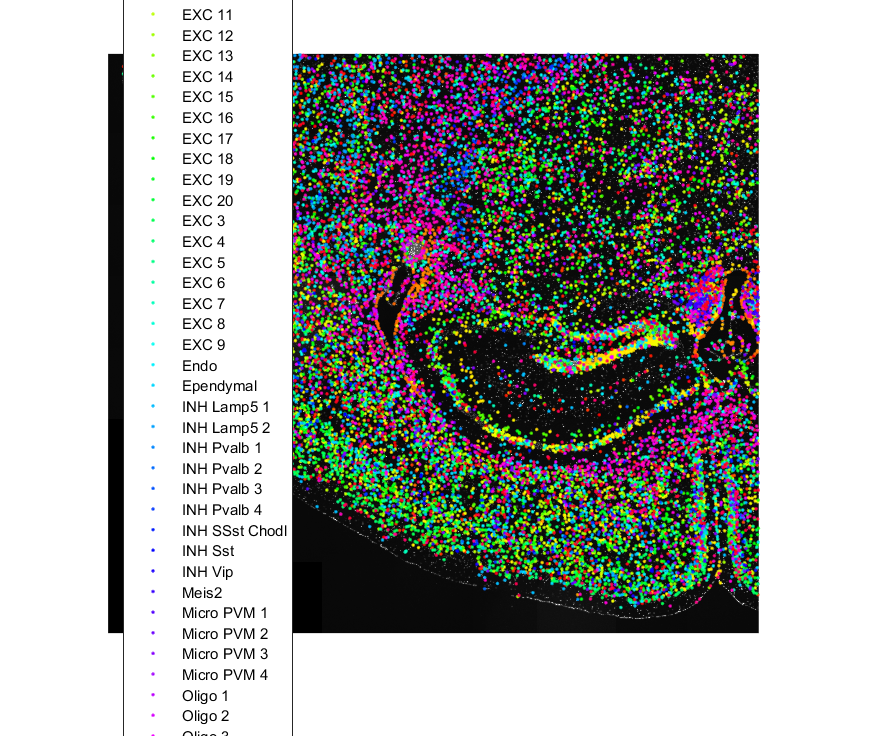

figure
imshow(IDAPI*20)
hold on 
gscatter(counts(:,3),counts(:,2),categorical(clusterNAME));

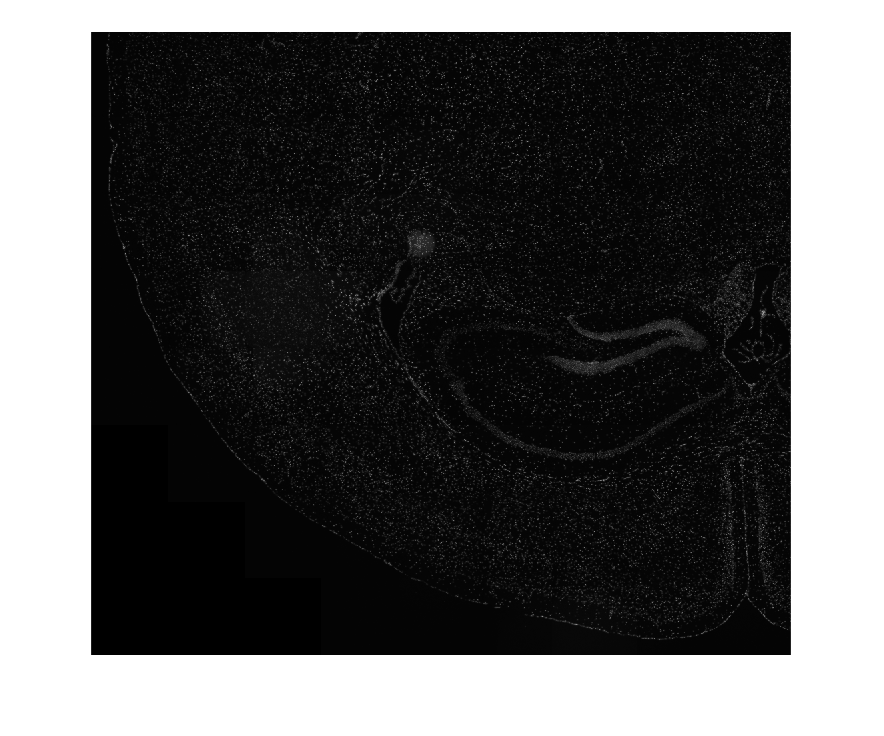


[Coord, Coord_write, blank] = drawpolygon(IDAPI,1,1);


COUN=inpolygon(counts(:,3), counts(:,2), Coord_write(:,2), Coord_write(:,3));
countsOSM=counts(COUN,:);

figure
imshow(IDAPI*20)
hold on 
gscatter(countsOSM(:,3),countsOSM(:,2));

genexpOSM=countsOSM(:,[4:53]);
genexpenOSM=genexpOSM;
AREA=countsOSM(:,end);
genexpOSM=genexpOSM./std(genexpOSM);
%genexpOSMen=genexpOSM;


%%%%%%%%%%%SUBSET OF GENES%%%%%%%%%%%%%%%%%
GENES=readcell('O:\directRNA\OSMfishData\genenamesOSMFISH.csv');

USEDNAMES={'Mbp','Slc17a7','Lamp5','Cd24a','Gad2','Cnr1','Pthlh','Crhbp','Slc32a1',...
'Vip','Tbr1','Kcnip2','Crh','Cpne5','Rorb','Serpinf1','Gfap','Aldoc','Syt6','Mfge8','Cemip2','Pdgfra','Plp1',...
'Sox10','Itpr2','Hexb','Anln','Bmp4','Ctps','Mrc1','Acta2','Apln','Flt1','Vtn','Ttr','Synpr','Npy',...
'Sst','Foxj1','Pcp4','Calm2','Gad1','Pvalb','Penk','Rgs4','Nrn1','Tac2','Calb2','Slc6a1','Enc1'};

GOOD=ismember(USEDNAMES,GENES);

genexpenOSMsubset=genexpOSM(:,GOOD);
%genexpOSMsubset=((genexpenOSMsubset+0.0001)'./(sum(genexpenOSMsubset')))';
%genexpNORMOSM=(((genexpenOSMsubset+0.0001)')./sum(genexpenOSMsubset'))';
[reduction,umap,clusterOSM]=run_umap(genexpenOSMsubset,'n_neighbors',140,'min_dist',0.1);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

[reduction,umap,clusterOSM]=run_umap(genexpOSM(:,2:end));

figure
imshow(IDAPI*30)
hold on
gscatter(countsOSM(:,3),countsOSM(:,2),clusterOSM');

figure
gscatter(reduction(:,1),reduction(:,2),clusterOSM');



CHANGE=readtable('O:\directRNA\50plex_MAY\CellMap_50PLEX_X1\CORRECT\Analysis_wholeSection_DENSITY_8JUNE\clusters_annotations_65clusters_8JUNE.csv');
clusterNAME=clusterOSM;
clusterNAME=num2cell(clusterNAME);
UNQ=unique(CHANGE.Var1);
clusterNAMES=clusterNAME;
for cas=1:size(UNQ,1)
  numb=UNQ(cas);
   clusterNAME(ismember(cell2mat(clusterNAMES),numb))=CHANGE.Var2(cas);
end


%CORRESPONDANCE BETWEEN INITIAL CLUSTERS AND CURRENT ONES
initialCLUSTERS=cluster(COUN);
[clustersMatch,chi2,p,COMPlabels]=crosstab(initialCLUSTERS,clusterOSM);
figure
clustergram(clustersMatch,'RowLabels', COMPlabels(1:41,1),'ColumnLabels',COMPlabels(:,2),'Colormap',parula,...
     'Standardize','row');
figure
 heatmap(COMPlabels(:,2),COMPlabels(1:56,1),clustersMatch,'Colormap',parula);

 clusterOSM=clusterNAME;
 UNICLUSTER=unique(clusterOSM);
CLUSEXP=[];
for clu=1:size(UNICLUSTER,2)
    clus=UNICLUSTER(clu);
    ci=genexpenOSMsubset(ismember(clusterOSM,clus),:);
    if size(ci,1)>1
    CLUSEXP=[CLUSEXP;mean(ci)];
    else 
    CLUSEXP=[CLUSEXP;ci];   
    end    
end
 
 
% Plot
USEDNAMES={'Mbp','Slc17a7','Lamp5','Cd24a','Gad2','Cnr1','Pthlh','Crhbp','Slc32a1',...
'Vip','Tbr1','Kcnip2','Crh','Cpne5','Rorb','Serpinf1','Gfap','Aldoc','Syt6','Mfge8','Cemip2','Pdgfra','Plp1',...
'Sox10','Itpr2','Hexb','Anln','Bmp4','Ctps','Mrc1','Acta2','Apln','Flt1','Vtn','Ttr','Synpr','Npy',...
'Sst','Foxj1','Pcp4','Calm2','Gad1','Pvalb','Penk','Rgs4','Nrn1','Tac2','Calb2','Slc6a1','Enc1'};

figure
clustergram(CLUSEXP,'ColumnLabels',USEDNAMES(GOOD),'RowLabels',UNICLUSTER,'Colormap',redbluecmap,...
   'Standardize','column');
%colormapeditor
figure
clustergram(CLUSEXP','ColumnLabels',UNICLUSTER,'RowLabels',USEDNAMES(GOOD),'Colormap',redbluecmap(20),...
   'Standardize','row');
%colormapeditor
 
 


USEDNAMES={'Mbp','Slc17a7','Lamp5','Cd24a','Gad2','Cnr1','Pthlh','Crhbp','Slc32a1',...
'Vip','Tbr1','Kcnip2','Crh','Cpne5','Rorb','Serpinf1','Gfap','Aldoc','Syt6','Mfge8','Tmem6','Pdgfra','Plp1',...
'Sox10','Itpr2','Hexb','Anln','Bmp4','Ctps','Mrc1','Acta2','Apln','Flt1','Vtn','Ttr','Synpr','Npy',...
'Sst','Foxj1','Pcp4','Calm2','Gad1','Pvalb','Penk','Rgs4','Nrn1','Tac2','Calb2','Slc6a1','Enc1'};

% EXPRESSEDCLUSTERS=array2table(CLUSEXP');
% EXPRESSEDCLUSTERS.Properties.RowNames={'Mbp','Slc17a7','Lamp5','Cd24a','Gad2','Cnr1','Pthlh','Crhbp','Slc32a1',...
% 'Vip','Tbr1','Kcnip2','Crh','Cpne5','Rorb','Serpinf1','Gfap','Aldoc','Syt6','Mfge8','Tmem6','Pdgfra','Plp1',...
% 'Sox10','Itpr2','Hexb','Anln','Bmp4','Ctps','Mrc1','Acta2','Apln','Flt1','Vtn','Ttr','Synpr','Npy',...
% 'Sst','Foxj1','Pcp4','Calm2','Gad1','Pvalb','Penk','Rgs4','Nrn1','Tac2','Calb2','Slc6a1','Enc1'};

 
EXPRESSEDCLUSTERS=array2table(CLUSEXP');
EXPRESSEDCLUSTERS.Properties.RowNames=USEDNAMES(GOOD);
EXPRESSEDCLUSTERS = sortrows( EXPRESSEDCLUSTERS,'RowNames');
%CL=num2str(UNICLUSTER');
CL=UNICLUSTER;
EXPRESSEDCLUSTERS.Properties.VariableNames=cellstr(CL);

osmfish

Here we combine it withOSMFISH


me=readcell('O:\directRNA\OSMfishData\matrixOSMFISH.csv');
%MEAN=readcell('O:\dRNA project\scRNAseqCortex\subclass_matrix.csv');
%me=MEAN(:,1);
me{1,1}='EMPTY';

GENES=readcell('O:\directRNA\OSMfishData\genenamesOSMFISH.csv');
SELECT=me;
ALL=SELECT;
ALLTAB=cell2table(ALL(2:end,:)');
NAMES=readcell('O:\directRNA\OSMfishData\clustersOSMFISH.csv');
ALLTAB.Properties.VariableNames=NAMES(:,1);
ALLTAB.Properties.RowNames=GENES;
%ALLTAB=ALLTAB(:,2:end);
ALLTAB = sortrows( ALLTAB ,'RowNames');
TEMALLTA=ALLTAB.Properties.RowNames;
ALLTAB=(table2array(ALLTAB)'./std(table2array(ALLTAB)'))';
ALLTAB=array2table(ALLTAB);
ALLTAB.Properties.VariableNames=NAMES(:,1);
ALLTAB.Properties.RowNames=TEMALLTA;
figure
clustergram(table2array(ALLTAB),'RowLabels', ALLTAB.Properties.RowNames,'ColumnLabels',ALLTAB.Properties.VariableNames,'Colormap',parula,...
     'Standardize','column');

figure
heatmap(ALLTAB.Properties.VariableNames,ALLTAB.Properties.RowNames,table2array(ALLTAB),'GridVisible','off','Colormap',parula,...
    'ColorScaling',"scaledrows")




Now we combine both datasets together

SUBEXPRESSED=EXPRESSEDCLUSTERS(ismember(EXPRESSEDCLUSTERS.Properties.RowNames,ALLTAB.Properties.RowNames),:);



corrmat=zeros(size(ALLTAB,2),size(SUBEXPRESSED,2));
for x=1:size(ALLTAB,1)
   for y=1:size(SUBEXPRESSED,2)
      coe=corrcoef(table2array(ALLTAB(:,x)),table2array(SUBEXPRESSED(:,y)));
       corrmat(x,y)=coe(2,1);
   end
end

figure
clustergram(corrmat,'RowLabels',ALLTAB.Properties.VariableNames,'ColumnLabels', EXPRESSEDCLUSTERS.Properties.VariableNames,...
    'Colormap',parula,'Standardize','column');

figure
clustergram(corrmat,'RowLabels',ALLTAB.Properties.VariableNames,'ColumnLabels', EXPRESSEDCLUSTERS.Properties.VariableNames,...
    'Colormap',parula);

figure
heatmap(EXPRESSEDCLUSTERS.Properties.VariableNames,ALLTAB.Properties.VariableNames,corrmat,'GridVisible','off','Colormap',parula,...
    'ColorScaling',"scaledcolumns")


## Representing top correlated clusters

MICRO_EXPRESSED=SUBEXPRESSED.("INH Vip");
MICRO_OSM=ALLTAB.InhibitoryVip;
figure
scatter(MICRO_EXPRESSED,MICRO_OSM,5,'red','filled');
ylabel('OSM')
xlabel('DRNA HYBISS')
title('DRNA VS OSM =INH VIP')
text(MICRO_EXPRESSED,MICRO_OSM,EXPRESSEDCLUSTERS.Properties.RowNames,'FontSize',12)

SUBSUBALLTAB=SUBALLTAB(ismember(SUBALLTAB.Properties.RowNames,SUBEXPRESSED.Properties.RowNames),:);
MICRO_SCRNA=SUBSUBALLTAB.("Choroid epithelial cells")
figure
scatter(MICRO_SCRNA,MICRO_OSM);
title('SCRNA VS OSM')

figure
scatter(MICRO_EXPRESSED,MICRO_SCRNA);
title('DRNA VS SCRNA')


MICRO_EXPRESSED=SUBEXPRESSED.("VS Muscle 1");
MICRO_SCRNA=SUBALLTAB.("Vascular smooth muscle cells");
figure
scatter(MICRO_EXPRESSED,MICRO_SCRNA);

# Working with single cell data


CHANGE=readtable('O:\directRNA\50plex_MAY\CellMap_50PLEX_X1\CORRECT\Analysis_subSection_8JUNE\clusters_annotations_34_clusters_OSMFISH_8_JUNE.csv');
clusterNAME=clusterOSM;
clusterNAME=num2cell(clusterNAME);
UNQ=unique(CHANGE.Var1);
clusterNAMES=clusterNAME;
for cas=1:size(UNQ,1)
  numb=UNQ(cas);
   clusterNAME(ismember(cell2mat(clusterNAMES),numb))=CHANGE.Var2(cas);
end


%CORRESPONDANCE BETWEEN INITIAL CLUSTERS AND CURRENT ONES
initialCLUSTERS=cluster(COUN);
[clustersMatch,chi2,p,COMPlabels]=crosstab(initialCLUSTERS,clusterOSM);
figure
clustergram(clustersMatch,'RowLabels', COMPlabels(1:41,1),'ColumnLabels',COMPlabels(:,2),'Colormap',parula,...
     'Standardize','row');
figure
 heatmap(COMPlabels(:,2),COMPlabels(1:56,1),clustersMatch,'Colormap',parula);

 
 clusterOSM=clusterNAME;
 UNICLUSTER=unique(clusterOSM);
CLUSEXP=[];
for clu=1:size(UNICLUSTER,2)
    clus=UNICLUSTER(clu);
    ci=genexpOSM(ismember(clusterOSM,clus),:);
    if size(ci,1)>1
    CLUSEXP=[CLUSEXP;mean(ci)];
    else 
    CLUSEXP=[CLUSEXP;ci];   
    end    
end
 
 
% Plot
USEDNAMES={'Mbp','Slc17a7','Lamp5','Cd24a','Gad2','Cnr1','Pthlh','Crhbp','Slc32a1',...
'Vip','Tbr1','Kcnip2','Crh','Cpne5','Rorb','Serpinf1','Gfap','Aldoc','Syt6','Mfge8','Cemip2','Pdgfra','Plp1',...
'Sox10','Itpr2','Hexb','Anln','Bmp4','Ctps','Mrc1','Acta2','Apln','Flt1','Vtn','Ttr','Synpr','Npy',...
'Sst','Foxj1','Pcp4','Calm2','Gad1','Pvalb','Penk','Rgs4','Nrn1','Tac2','Calb2','Slc6a1','Enc1'};

figure
clustergram(CLUSEXP,'ColumnLabels',USEDNAMES,'RowLabels',UNICLUSTER,'Colormap',redbluecmap,...
   'Standardize','column');
%colormapeditor
figure
clustergram(CLUSEXP','ColumnLabels',UNICLUSTER,'RowLabels',USEDNAMES(GOOD),'Colormap',redbluecmap(20),...
   'Standardize','row');
%colormapeditor
 
 


USEDNAMES={'Mbp','Slc17a7','Lamp5','Cd24a','Gad2','Cnr1','Pthlh','Crhbp','Slc32a1',...
'Vip','Tbr1','Kcnip2','Crh','Cpne5','Rorb','Serpinf1','Gfap','Aldoc','Syt6','Mfge8','Tmem6','Pdgfra','Plp1',...
'Sox10','Itpr2','Hexb','Anln','Bmp4','Ctps','Mrc1','Acta2','Apln','Flt1','Vtn','Ttr','Synpr','Npy',...
'Sst','Foxj1','Pcp4','Calm2','Gad1','Pvalb','Penk','Rgs4','Nrn1','Tac2','Calb2','Slc6a1','Enc1'};

 
EXPRESSEDCLUSTERS=array2table(CLUSEXP');
EXPRESSEDCLUSTERS.Properties.RowNames=USEDNAMES;
EXPRESSEDCLUSTERS = sortrows( EXPRESSEDCLUSTERS,'RowNames');
%CL=num2str(UNICLUSTER');
CL=UNICLUSTER;
EXPRESSEDCLUSTERS.Properties.VariableNames=cellstr(CL);

scDATA

Here we combine it with SCDATA


me=readcell('O:\directRNA\50plex_MAY\CLUSTER5_SECTION3\CLUSTER5_SECTION\MatrixLINARSSON2020_LEV5_SECTION.csv');
%MEAN=readcell('O:\dRNA project\scRNAseqCortex\subclass_matrix.csv');
%me=MEAN(:,1);
me{1,1}='EMPTY';

GENES=readcell('O:\directRNA\50plex_MAY\CLUSTER5_SECTION3\CLUSTER5_SECTION\genenamesLINARSSON2020_LEV5_SECTION.csv');
SELECT=me;
ALL=SELECT;
ALLA=ALL(2:end,:);
NAMES=readcell('O:\directRNA\50plex_MAY\CLUSTER5_SECTION3\CLUSTER5_SECTION\clustersLINARSSON2020_LEV5_SECTION.csv');
GENESSEL={'Mbp','Slc17a7','Lamp5','Cd24a','Gad2','Cnr1','Pthlh','Crhbp','Slc32a1',...
'Vip','Tbr1','Kcnip2','Crh','Cpne5','Rorb','Serpinf1','Gfap','Aldoc','Syt6','Mfge8','Tmem2','Pdgfra','Plp1',...
'Sox10','Itpr2','Hexb','Anln','Bmp4','Ctps','Mrc1','Acta2','Apln','Flt1','Vtn','Ttr','Synpr','Npy',...
'Sst','Foxj1','Pcp4','Calm2','Gad1','Pvalb','Penk','Rgs4','Nrn1','Tac2','Calb2','Slc6a1','Enc1'};
ASA=ismember(GENES,GENESSEL);

SELECTMATRIX=ALLA(:,ASA);
SELECTGENES=GENES(ASA);

ALLTAB=cell2table(SELECTMATRIX(1:end,:)');

ALLTAB.Properties.VariableNames=NAMES(:,1);
ALLTAB.Properties.RowNames=SELECTGENES;
%ALLTAB=ALLTAB(:,2:end);
ALLTAB = sortrows( ALLTAB ,'RowNames');
TEMALLTA=ALLTAB.Properties.RowNames;

ALLTAB=(table2array(ALLTAB)'./std((table2array(ALLTAB)+0.00001)'))';
ALLTAB=array2table(ALLTAB);

ALLTAB.Properties.VariableNames=NAMES(:,1);
ALLTAB.Properties.RowNames=TEMALLTA;
figure
clustergram(table2array(ALLTAB),'RowLabels', ALLTAB.Properties.RowNames,'ColumnLabels',ALLTAB.Properties.VariableNames,'Colormap',parula,...
     'Standardize','column');

figure
heatmap(ALLTAB.Properties.VariableNames,ALLTAB.Properties.RowNames,table2array(ALLTAB),'GridVisible','off','Colormap',parula,...
    'ColorScaling',"scaledrows")




SUBEXPRESSED=EXPRESSEDCLUSTERS(ismember(EXPRESSEDCLUSTERS.Properties.RowNames,ALLTAB.Properties.RowNames),:);
SUBALLTAB=ALLTAB(ismember(ALLTAB.Properties.RowNames,EXPRESSEDCLUSTERS.Properties.RowNames),:);



corrmat=zeros(size(SUBALLTAB,2),size(SUBEXPRESSED,2));
for x=1:size(SUBALLTAB,2)
   for y=1:size(SUBEXPRESSED,2)
      coe=corrcoef(table2array(SUBALLTAB(:,x)),table2array(SUBEXPRESSED(:,y)));
      corrmat(x,y)=coe(2,1);
   end
end

figure
clustergram(corrmat,'RowLabels',SUBALLTAB.Properties.VariableNames,'ColumnLabels', SUBEXPRESSED.Properties.VariableNames,...
    'Colormap',parula);%,'Standardize','column');

figure
clustergram(corrmat,'RowLabels',SUBALLTAB.Properties.VariableNames,'ColumnLabels', SUBEXPRESSED.Properties.VariableNames,...
    'Colormap',parula,'Standardize','column');


figure
heatmap(EXPRESSEDCLUSTERS.Properties.VariableNames,SUBALLTAB.Properties.VariableNames,corrmat,'GridVisible','off','Colormap',parula,...
    'ColorScaling',"scaledcolumns")

## Representing top correlated clusters

MICRO_EXPRESSED=SUBEXPRESSED.("Pyramidal 2")
MICRO_SCRNA=SUBALLTAB.TEGLU10;
figure
scatter(MICRO_EXPRESSED,MICRO_SCRNA);
ylabel('SCRNASEQ')
xlabel('DRNA HYBISS')
title('DRNA VS OSM =Pyramidal2/TEGLU10')
text(MICRO_EXPRESSED,MICRO_SCRNA,SUBALLTAB.Properties.RowNames,"FontSize",12)



MICRO_EXPRESSED=SUBEXPRESSED.("Peri. Macroph.");
MICRO_SCRNA=SUBALLTAB.("Perivascular macrophages");
figure
scatter(MICRO_EXPRESSED,MICRO_SCRNA);

# Representing cell types

UNICS=unique(clusterNAME);
CMP=CellMap;

for as=1:size(UNICS,2)
  disp(as)
  CACACA=UNICS(as);    
  SELS=ismember(clusterNAME,CACACA);
  NUMBERE=counts(SELS,1);
  CMP(ismember(CMP,NUMBERE))=as+300000;
end

if Debug
    figure(302)
    imshow(IDAPI*20)
    hold on
    CAS=label2rgb(CMP, 'hsv', 'k', 'shuffle');

    h=imshow(CAS);

end

## **Simulating combinatorial**

 clusterOSM=clusterNAME;
 UNICLUSTER=unique(clusterOSM);
CLUSEXP=[];
for clu=1:size(UNICLUSTER,2)
    clus=UNICLUSTER(clu);
    ci=genexpenOSM(ismember(clusterOSM,clus),:);
    if size(ci,1)>1
    CLUSEXP=[CLUSEXP;mean(ci)];
    else 
    CLUSEXP=[CLUSEXP;ci];   
    end    
end
 
 


figure
clustergram(CLUSEXP,'ColumnLabels',USEDNAMES,'RowLabels',UNICLUSTER,'Colormap',redbluecmap,...
   'Standardize','column');
%colormapeditor

 

EXPRESSEDCLUSTERS=array2table(CLUSEXP');
EXPRESSEDCLUSTERS.Properties.RowNames={'Mbp','Slc17a7','Lamp5','Cd24a','Gad2','Cnr1','Pthlh','Crhbp','Slc32a1',...
'Vip','Tbr1','Kcnip2','Crh','Cpne5','Rorb','Serpinf1','Gfap','Aldoc','Syt6','Mfge8','Tmem6','Pdgfra','Plp1',...
'Sox10','Itpr2','Hexb','Anln','Bmp4','Ctps','Mrc1','Acta2','Apln','Flt1','Vtn','Ttr','Synpr','Npy',...
'Sst','Foxj1','Pcp4','Calm2','Gad1','Pvalb','Penk','Rgs4','Nrn1','Tac2','Calb2','Slc6a1','Enc1'};

 
EXPRESSEDCLUSTERS=array2table(CLUSEXP');
EXPRESSEDCLUSTERS.Properties.RowNames=USEDNAMES;
EXPRESSEDCLUSTERS = sortrows( EXPRESSEDCLUSTERS,'RowNames');
%CL=num2str(UNICLUSTER');
CL=UNICLUSTER;
EXPRESSEDCLUSTERS.Properties.VariableNames=cellstr(CL);



[GENES1,SUB1,GENES2,SUB2]=create_subpanels(CLUSEXP,cellstr(CL)',USEDNAMES)


figure
bar(categorical(cellstr(CL)'),sum(CLUSEXP'));
figure
bar(categorical(cellstr(CL)'),sum(SUB1'));
figure
bar(categorical(cellstr(CL)'),sum(SUB2'));



%SINGLE CELL DATA
CLASSSC=ALLTAB.Properties.VariableNames;
GENESSC=ALLTAB.Properties.RowNames;
ALLTABSC=table2array(ALLTAB)';

figure
bar(categorical(CLASSSC'),sum(ALLTABSC'));

[GENES1,SUB1,GENES2,SUB2]=create_subpanels(CLUSEXP,cellstr(CL)',USEDNAMES)
